# Exploring nwb file generated from november_whiskey_bravo

#### *J.A. Westerberg, Ph.D. (*[*westerberg-science*](https://github.com/westerberg-science)*; *[*j.westerberg@nin.knaw.nl*](mailto:j.westerberg@nin.knaw.nl)*)*

*Department of Vision and Cognition, Netherlands Institute for Neuroscience*

`written: 31-03-2023`

`updated: 03-08-2023`

where is your nwb file located?

path_to_nwb = "D:\_VandC_DATA_PIPELINE\_6_NWB_DATA\sub-N-ses-20230605-exp-Stim1_exp1_2023.nwb";

and what was the experiment called (for future examples)...

exp_name = 'Stim1_exp1_2023';

load nwb

nwb = nwbRead(path_to_nwb)

nwb =   NwbFile with properties:

                                             nwb_version: '2.4.0'
                                        file_create_date: [1×1 types.untyped.DataStub]
                         general_source_script_file_name: []
                                              identifier: 'sub-N-ses-20230605-exp-Stim1_exp1_2023'
                                     session_description: []
                                      session_start_time: 2023-06-05T00:00:00.000000+02:00
                               timestamps_reference_time: 2023-06-05T00:00:00.000000+02:00
                                             acquisition: [20×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: []
                                      

notice that many fields are empty. This is because nwb defines certain categories that can be populated - it is our duty to populate the correct fields with their relevant information. that means for data types which we don't deal with (e.g., optophysiology), our files will always have that field empty.

print the session id, institution, and lab!

disp([nwb.identifier '   ' nwb.general_lab '   ' nwb.general_institution])

sub-N-ses-20230605-exp-Stim1_exp1_2023   Vision and Cognition   Netherlands Institute for Neuroscience - KNAW


ElectricalSeries is an nwb class that usually houses data such as LFP, MUA, etc... does this file have any electrical series data present? This searchFor function built into the nwb toolkit is something that could come in handy with files you are unfamiliar with

nwb.searchFor('electricalseries')

ans =   Map with properties:

        Count: 17
      KeyType: char
    ValueType: any


notice that it has found 18 distinct electricalseries, is that what you were expecting?

useful data will be stored in a few places, e.g.: the information for each of the probes (or instances as how the Blackrock conversion works)

nwb.general_extracellular_ephys

ans =   8×1 Set array with properties:

    probeA: [types.core.ElectrodeGroup]
    probeB: [types.core.ElectrodeGroup]
    probeC: [types.core.ElectrodeGroup]
    probeD: [types.core.ElectrodeGroup]
    probeE: [types.core.ElectrodeGroup]
    probeF: [types.core.ElectrodeGroup]
    probeG: [types.core.ElectrodeGroup]
    probeH: [types.core.ElectrodeGroup]


individual electrodes

nwb.general_extracellular_ephys_electrodes

ans =   DynamicTable with properties:

       colnames: {9×1 cell}
    description: 'no description'
             id: [1×1 types.hdmf_common.ElementIdentifiers]
     vectordata: [9×1 types.untyped.Set]


'raw' data is stored in the acquisition field. It isn't truly the raw data as recorded by the ephys system, but I wanted to follow the lead of some of my collaborators who placed these types of data here.

nwb.acquisition

ans =   20×1 Set array with properties:

           eye_1_tracking_dev_0: [types.core.EyeTracking]
    photodiode_1_tracking_dev_0: [types.core.BehavioralTimeSeries]
                    probe_0_lfp: [types.core.LFP]
                   probe_0_muae: [types.core.LFP]
                    probe_1_lfp: [types.core.LFP]
                   probe_1_muae: [types.core.LFP]
                    probe_2_lfp: [types.core.LFP]
                   probe_2_muae: [types.core.LFP]
                    probe_3_lfp: [types.core.LFP]
                   probe_3_muae: [types.core.LFP]
                    probe_4_lfp: [types.core.LFP]
                   probe_4_muae: [types.core.LFP]
                    probe_5_lfp: [types.core.LFP]
                   probe_5_muae: [types.core.LFP]
                    probe_6_lfp: [types.core.LFP]
                   probe_6_muae: [types.core.LFP]
                    probe_7_lfp: [types.core.LFP]
          

kilosorted single unit characteristics and spike times

nwb.units

ans =   Units with properties:

          electrode_group: []
               electrodes: []
         electrodes_index: []
            obs_intervals: []
      obs_intervals_index: []
              spike_times: [1×1 types.hdmf_common.VectorData]
        spike_times_index: [1×1 types.hdmf_common.VectorIndex]
            waveform_mean: [1×1 types.hdmf_common.VectorData]
              waveform_sd: []
                waveforms: []
          waveforms_index: []
    waveforms_index_index: []
                 colnames: {31×1 cell}
              description: 'kilosorted and AllenSDK ecephys processed units'
                       id: [1×1 types.hdmf_common.ElementIdentifiers]
               vectordata: [32×1 types.untyped.Set]


and processed data, here you will probably see the convolved spike trains, for example

nwb.processing

ans =   Set with properties:

    convolved_spike_train: [types.core.ProcessingModule]


finally, the intervals data - which are the discrete timestamped data types

nwb.intervals

ans =   2×1 Set array with properties:

                  Stim1_exp1_2023_dev_0: [types.core.TimeIntervals]
    photodiode_1_detected_changes_dev_0: [types.core.TimeIntervals]


because nwb files keep data in storage until requested, you will have to 'get' the data you want...take for example:

nwb.acquisition.get('probe_0_lfp')

ans =   LFP with properties:

    electricalseries: [1×1 types.untyped.Set]


however, we still aren't at the data! because I formatted this to match AIBS nwb specs, you will find that data tend to be buried under several layers of hierarchical input. Let's dig deeper...

nwb.acquisition.get('probe_0_lfp').electricalseries

ans =   Set with properties:

    probe_0_lfp_data: [types.core.ElectricalSeries]


looks like we still aren't there quite yet...and it looks like this will be a call to a named variable rather than a class, so we have to 'get' the data. What do I mean by this. nwb recognizes classes, but when you arrive at a data type that was named specifically by the user (e.g., Jake named the lfp data 'probe_0_lfp_data'), that information has to be retrieved by the get function. let's keep digging...

nwb.acquisition.get('probe_0_lfp').electricalseries.get('probe_0_lfp_data')

ans =   ElectricalSeries with properties:

    channel_conversion_axis: 1
                 electrodes: [1×1 types.hdmf_common.DynamicTableRegion]
         channel_conversion: []
                  filtering: '4th order Butterworth 1-250 Hz'
         starting_time_unit: 'seconds'
        timestamps_interval: 1
            timestamps_unit: 'seconds'
                       data: [1×1 types.untyped.DataStub]
                  data_unit: 'uV'
         starting_time_rate: 1000
                   comments: 'no comments'
                    control: []
        control_description: []
            data_continuity: []
            data_conversion: 1
            data_resolution: -1
                description: 'no description'
              starting_time: 0
                 timestamps: [1×1 types.untyped.DataStub]


et voila! it looks like we are inspecting the data now. let's poke around...but first, we can create a 'shortcut' to this data

lfp = nwb.acquisition.get('probe_0_lfp').electricalseries.get('probe_0_lfp_data');

now we don't have to type so much and the information is still stored and made available in the same way. (Think of it as creating a desktop shortcut to an application on your computer)

lfp

lfp =   ElectricalSeries with properties:

    channel_conversion_axis: 1
                 electrodes: [1×1 types.hdmf_common.DynamicTableRegion]
         channel_conversion: []
                  filtering: '4th order Butterworth 1-250 Hz'
         starting_time_unit: 'seconds'
        timestamps_interval: 1
            timestamps_unit: 'seconds'
                       data: [1×1 types.untyped.DataStub]
                  data_unit: 'uV'
         starting_time_rate: 1000
                   comments: 'no comments'
                    control: []
        control_description: []
            data_continuity: []
            data_conversion: 1
            data_resolution: -1
                description: 'no description'
              starting_time: 0
                 timestamps: [1×1 types.untyped.DataStub]


how do we grab the data? Well if we just make this call...

lfp.data

ans =   DataStub with properties:

    filename: "D:\_VandC_DATA_PIPELINE\_6_NWB_DATA\sub-N-ses-20230605-exp-Stim1_exp1_2023.nwb"
        path: '/acquisition/probe_0_lfp/probe_0_lfp_data/data'
        dims: [128 1737828]
       ndims: 2
    dataType: 'double'


we don't end up with a nice matrix of data. Instead we find a pointer to where the data is stored in memory. However, we do get some useful metadata. Okay, now let's really grab the data and load it into memory (but only every 10th channel for sake of this tutorial)!

loaded_lfp = lfp.data(1:10:end,:);

and look at some of the data...

loaded_lfp(:, 1:10)

ans =    -1.2793   37.1237   49.8698   51.2714   49.2761   45.4288   43.0459   41.5631   38.1414   34.5927
    3.9499   44.5572   57.9663   58.3954   57.6331   56.7669   56.1254   54.4381   50.0423   45.9088
   -7.8723  -27.0689  -33.4108  -33.3633  -31.5355  -27.9513  -24.4275  -22.1705  -19.8210  -17.7801
   19.8985   17.8757    7.8440    6.9871    9.1798    4.7435   -6.8119  -19.7618  -25.2083  -25.4153
   34.6571   33.5501   28.8794   21.6626   14.9592    9.6435    8.4953    5.6666   -5.0123  -16.7590
   44.6910   63.7297   77.6171   89.3992   93.2712   85.9254   70.4503   56.8097   48.4863   38.0886
   60.6039   53.6623   53.4137   54.9383   51.9575   42.2907   25.9411    7.1212   -9.1354  -16.2945
   -5.5343   -7.3045  -10.3399  -12.5423  -15.9225  -21.7120  -28.7735  -37.8572  -48.3778  -56.2405
   11.0118   10.6648   11.6585   10.5816    7.4010    3.8770   -0.2333   -4.9968  -10.9113  -18.6673
   21.5256   24.4678   24.2913   17.4293    9.9835    5.8636    2.8403   -2.6129   -9

let's load in some mua data as well for later on...

mua = nwb.acquisition.get('probe_0_muae').electricalseries.get('probe_0_muae_data');
loaded_mua = mua.data(1:10:end,:);

if you look at your system monitor, you should now see that your memory usage jumped! This is because we have now loaded all lfp data (for this probe, which is the only probe in the session I am looking at) into the workspace. now you may or may not want to do this moving forward as it can take up a lot of RAM, you may want to pull specific epochs of data rather than the whole continuous trace. but before we do that, let's investigate where those 5 rows of data come from!

which electrodes did these data come from

lfp.electrodes

ans =   DynamicTableRegion with properties:

          table: [1×1 types.untyped.ObjectView]
    description: 'probeA'
           data: [1×1 types.untyped.DataStub]


example_electrode_identifiers = lfp.electrodes.data(1:10:end);

let's learn about electrodes 0-12

example_electrode_indices = nan(numel(example_electrode_identifiers), 1);
ii_ctr = 0;
for ii = example_electrode_identifiers'
    ii_ctr = ii_ctr + 1;
    example_electrode_indices(ii_ctr) = find( ...
        nwb.general_extracellular_ephys_electrodes.id.data(:) == ii); 
end

What information can we grab?

nwb.general_extracellular_ephys_electrodes.vectordata

ans =   9×1 Set array with properties:

    filtering: [types.hdmf_common.VectorData]
        group: [types.hdmf_common.VectorData]
          imp: [types.hdmf_common.VectorData]
        label: [types.hdmf_common.VectorData]
     location: [types.hdmf_common.VectorData]
        probe: [types.hdmf_common.VectorData]
            x: [types.hdmf_common.VectorData]
            y: [types.hdmf_common.VectorData]
            z: [types.hdmf_common.VectorData]


how about location?

nwb.general_extracellular_ephys_electrodes.vectordata.get('location').data(example_electrode_indices)

ans = 13×1 cell array
    {'V1'}
    {'V1'}
    {'V1'}
    {'V1'}
    {'V1'}
    {'V1'}
    {'V1'}
    {'V1'}
    {'V1'}
    {'V1'}
    {'V1'}
    {'V1'}
    {'V1'}


and probe id (might not exist depending on the recording system)

nwb.general_extracellular_ephys_electrodes.vectordata.get('x').data(example_electrode_indices)

ans =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


let's pull out the indices for a couple of stimulus conditions to compare. what are the conditions that we can compare? put both values to the same stimbit if this cannot be obtained from the nwb as currently preprocessed.

bit_1 = 2;
bit_2 = 2;

and now pull the data

stimulus_1 = find(nwb.intervals.get([exp_name '_dev_0']).vectordata.get('codes').data(:) == bit_1);
stimulus_2 = find(nwb.intervals.get([exp_name '_dev_0']).vectordata.get('codes').data(:) == bit_2);
stimulus_2(1:5)

ans =      1
     2
     3
     4
     5


and their times

start_times_1 = nwb.intervals.get([exp_name '_dev_0']).start_time.data(stimulus_1);
start_times_2 = nwb.intervals.get([exp_name '_dev_0']).start_time.data(stimulus_2);
start_times_1(1:5)

ans =     1.0000
    3.0175
    5.0520
    7.1162
    9.1885


and align those times with the times in for the data timestamps. lfp and mua have the same timestamps, hence the shortcut of only grabbing indices from the lfp set

indices_1 = nearest_index(lfp.timestamps(:), start_times_1);
indices_2 = nearest_index(lfp.timestamps(:), start_times_2);
indices_1(1:5)

ans =         1001
        3018
        5053
        7117
        9190


and lastly, let's define a time window of interest for our visualizations below

time_window = [100 500];

then pull out the time windows of the events and baseline correct the data

trialwise_lfp_1 = epoch_data(loaded_lfp, indices_1, [time_window(1) time_window(2)]);
trialwise_lfp_2 = epoch_data(loaded_lfp, indices_2, [time_window(1) time_window(2)]);
trialwise_mua_1 = epoch_data(loaded_mua, indices_1, [time_window(1) time_window(2)]);
trialwise_mua_2 = epoch_data(loaded_mua, indices_2, [time_window(1) time_window(2)]);

corrected_lfp_1 = baseline_correct(trialwise_lfp_1, 1:time_window(1));
corrected_lfp_2 = baseline_correct(trialwise_lfp_2, 1:time_window(1));
corrected_mua_1 = baseline_correct(trialwise_mua_1, 1:time_window(1));
corrected_mua_2 = baseline_correct(trialwise_mua_2, 1:time_window(1));

plot some examples!

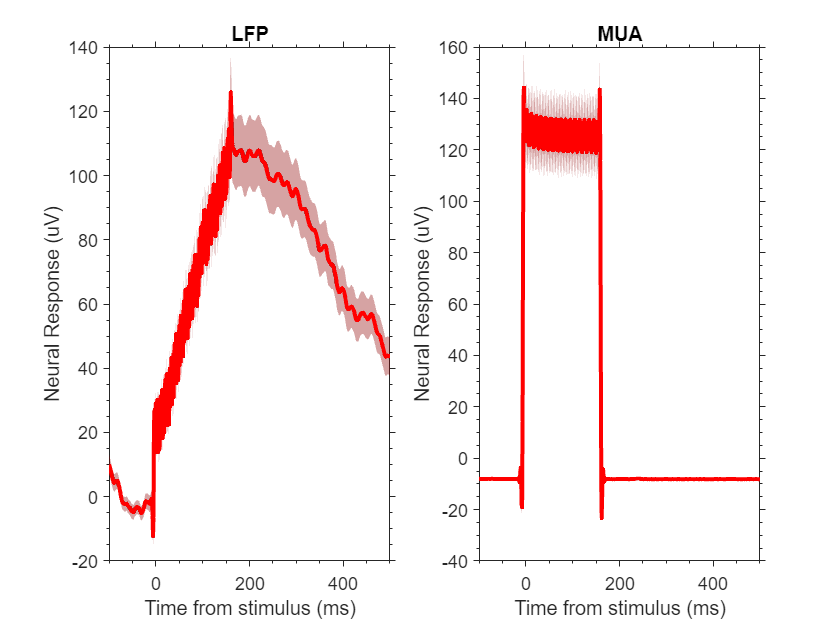

example_channel = 9;
figure;
subplot(1,2,1); hold on;
[m,l,u] = confidence_interval(corrected_lfp_2(example_channel,:,:));
plot_confidence_interval(l, u, -time_window(1):time_window(2), 'k', .2);
plot(-time_window(1):time_window(2), m, 'color', 'k', 'linewidth', 2)
[m,l,u] = confidence_interval(corrected_lfp_1(example_channel,:,:));
plot_confidence_interval(l, u, -time_window(1):500, 'r', .2);
plot(-time_window(1):time_window(2), m, 'color', 'r', 'linewidth', 2)
hold off;
title('LFP'); xlabel('Time from stimulus (ms)'); ylabel('Neural Response (uV)');
set(gca, 'xlim', [-time_window(1) time_window(2)], 'box', 'on', 'xminortick', 'on', 'yminortick', 'on', 'tickdir', 'out', 'linewidth', 1)

subplot(1,2,2); hold on;
[m,l,u] = confidence_interval(corrected_mua_2(example_channel,:,:));
plot_confidence_interval(l, u, -time_window(1):time_window(2), 'k', .2);
plot(-time_window(1):time_window(2), m, 'color', 'k', 'linewidth', 2)
[m,l,u] = confidence_interval(corrected_mua_1(example_channel,:,:));
plot_confidence_interval(l, u, -time_window(1):time_window(2), 'r', .2);
plot(-time_window(1):time_window(2), m, 'color', 'r', 'linewidth', 2)
hold off;
title('MUA'); xlabel('Time from stimulus (ms)'); ylabel('Neural Response (uV)');
set(gca, 'xlim', [-time_window(1) time_window(2)], 'box', 'on', 'xminortick', 'on', 'yminortick', 'on', 'tickdir', 'out', 'linewidth', 1)

spk = nwb.processing.get('convolved_spike_train').nwbdatainterface.get('convolved_spike_train_data');
good_units = find(nwb.units.vectordata.get('quality').data(:) == 1);
loaded_spk = spk.data(good_units,:);
indices_1 = nearest_index(spk.timestamps(:), start_times_1);
indices_2 = nearest_index(spk.timestamps(:), start_times_2);
trialwise_spk_1 = epoch_data(loaded_spk, indices_1, [time_window(1) time_window(2)]);
trialwise_spk_2 = epoch_data(loaded_spk, indices_2, [time_window(1) time_window(2)]);
corrected_spk_1 = baseline_correct(trialwise_spk_1, 1:time_window(1));
corrected_spk_2 = baseline_correct(trialwise_spk_2, 1:time_window(1));

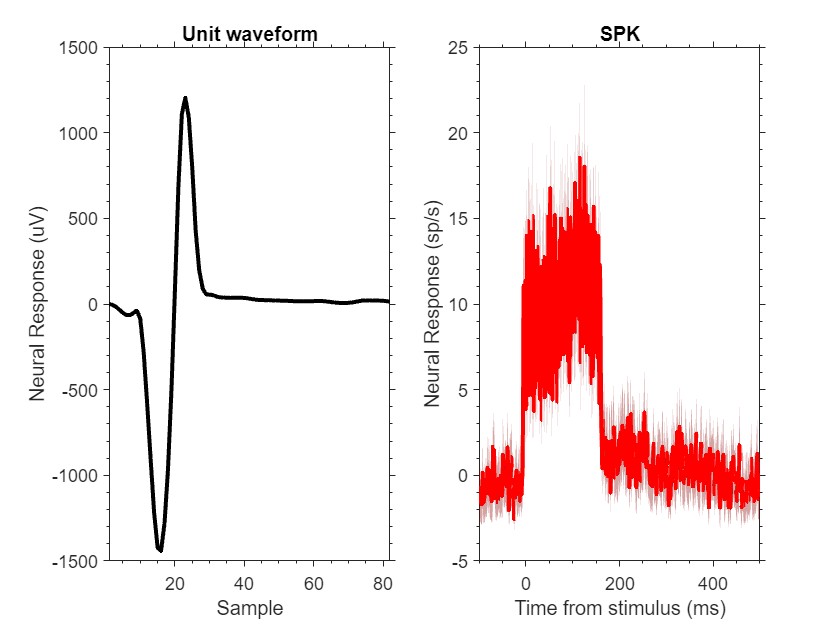

example_channel = 65;
figure; 
subplot(1,2,1); hold on;
plot(nwb_retrieve_waveform(nwb, example_channel, 128), 'color', 'k', 'linewidth', 2)
title('Unit waveform'); xlabel('Sample'); ylabel('Neural Response (uV)');
set(gca, 'xlim', [1 82], 'box', 'on', 'xminortick', 'on', 'yminortick', 'on', 'tickdir', 'out', 'linewidth', 1)
subplot(1,2,2); hold on;
[m,l,u] = confidence_interval(corrected_spk_2(example_channel,:,:));
plot_confidence_interval(l, u, -time_window(1):time_window(2), 'k', .2);
plot(-time_window(1):time_window(2), m, 'color', 'k', 'linewidth', 2)
[m,l,u] = confidence_interval(corrected_spk_1(example_channel,:,:));
plot_confidence_interval(l, u, -time_window(1):time_window(2), 'r', .2);
plot(-time_window(1):time_window(2), m, 'color', 'r', 'linewidth', 2)
hold off;
title('SPK'); xlabel('Time from stimulus (ms)'); ylabel('Neural Response (sp/s)');
set(gca, 'xlim', [-time_window(1) time_window(2)], 'box', 'on', 'xminortick', 'on', 'yminortick', 'on', 'tickdir', 'out', 'linewidth', 1)